% Calculo simbólico matlab

syms f1 f2 f3 d M


% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

f1 = 16*mm;
f2 = 200*mm;
M = 10;
d = 8*mm;

% Matriz de transferencia para la propagación de la distancia f1
propf1 = [1 f1; 0 1]

propf1 =     1.0000    0.0160
         0    1.0000


% Matriz de transferencia para el objetivo MO
objMO = [M 0; -1/f1 1/M]

objMO =    10.0000         0
  -62.5000    0.1000


% Matriz de transferencia para la propagación de la distancia d
propd = [1 d; 0 1]

propd =     1.0000    0.0080
         0    1.0000


%Lente LT 
LT = [1 0; -1/f2 1]

LT =      1     0
    -5     1




% Matriz de transferencia para la propagación de la distancia f2
propf2 = [1 f2; 0 1]

propf2 =     1.0000    0.2000
         0    1.0000


Msys = propf2*LT*propd*propf1*objMO*propf1

Msys =   -12.5000   -0.1800
 -105.0000   -1.5920


det(Msys)

ans = 1.0000

L0 = (2*f1+d)

L0 = 0.0400

A = Msys(1,1)

A = -12.5000

B = abs(Msys(1,2))

B = 0.1800

D = Msys(2,2)

D = -1.5920


% Tamaño de la representación
Nx = 1024;
Ny = 1024;



% Longitud de Onda de iluminación
lambda = 533*nm;

% Condiciones de muestreo
dx = (lambda*B/Nx)^(1/2);
dy = dx;

%Limite de propagacion
zlim = Nx*dx^2/lambda

zlim = 0.1800

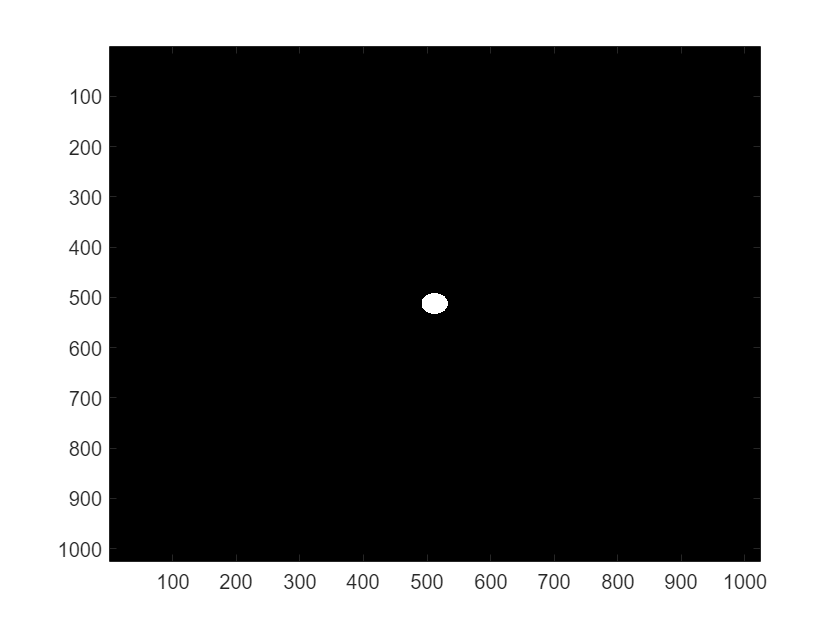


% Transmitancia
radioAberturaCirc = 200*um/dx; % Radio de 20um
aberturaCircular = filtroCircular ([Nx/2 Ny/2],radioAberturaCirc,[Ny Nx]);

pantalla1 = (aberturaCircular);
imagesc(pantalla1)
colormap gray

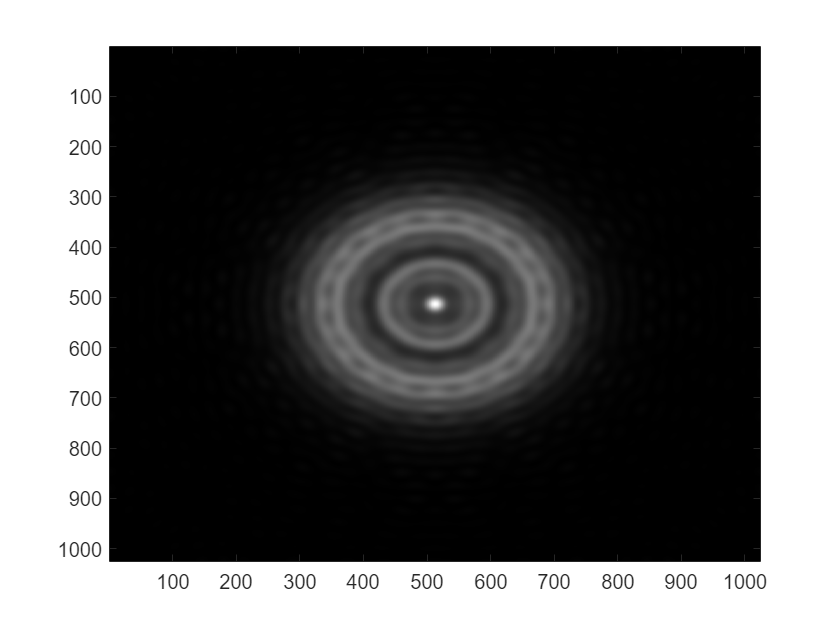

propagacionPantalla1 = transformadaFresnel(pantalla1,dx,dy,lambda,A,B,D,L0,"dft",false,"zoom",false);
intensidad1 = abs(propagacionPantalla1).^2;
imagesc(intensidad1)